%P 4.8
%(a),(b)
syms k s T_d

C_sys = k/(0.2*s+1);
P_sys = 100/(s^2+25*s+100);
L=C_sys*P_sys;
tf_sys = simplify(L/(1+L));
S_Tk = simplify(diff(tf_sys,k)*k/tf_sys)
Y=simplify(P_sys*T_d/(1+L))

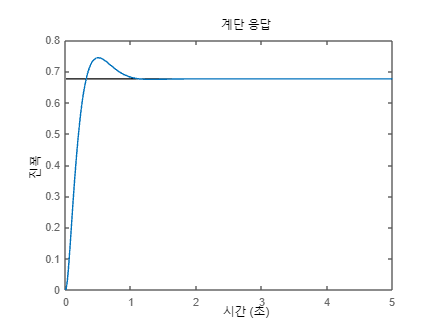


%(c)

t =0:0.01:5;
s = tf('s');
k=0.48;
C_sys = k/(0.2*s+1);
P_sys = 100/(s^2+25*s+100);
dist_cl=feedback(P_sys,C_sys);
step(dist_cl,t);


% sys_cl=feedback(C_sys*P_sys,1);
% step(sys_cl,t);
stepinfo(dist_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.2149
    TransientTime: 0.8981
     SettlingTime: 0.8981
      SettlingMin: 0.6093
      SettlingMax: 0.7435
        Overshoot: 10.0450
       Undershoot: 0
             Peak: 0.7435
         PeakTime: 0.5013


%P 4.17
%(a)

syms s t

theta_s = 600/(0.1*s^3 + s^2+600*s);
theta_t=simplify(ilaplace(theta_s,t))

$$theta\_t = 1-{\mathrm{e}}^{-5\,t}\,\left(\cos\left(5\,\sqrt{239}\,t\right)+\frac{\sqrt{239}\,\sin\left(5\,\sqrt{239}\,t\right)}{239}\right)$$


%(c)

limit(((1/s)*(1-600/(0.1*s^2+s+600))))

$$ans = \frac{1}{600}$$